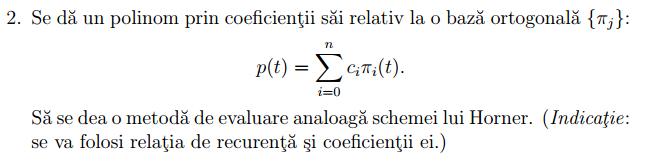

Pentru a baza ortogonala, putem folosi **polinoamele Chebyshev**, **polionamele Legendre** sau un **polinom ortogonal general pe un anumit interval si cu o functie**.

Toate aceste polinoame satisfac o recurenta formata din trei termeni, de forma:


$$\pi_{k+1}(x) = (a_kt + b_k)* \pi_k(t) + c_k\pi_{k-1}(t)$$


**Schema lui Horner**

Pentru polinoame de forma:

$p(x) = a_0 + a_1 * x + a_2 * x^2 + ... + a_n * x^n$,

polinomul se poate evalua astfel:

$p(x) = a_0 + x * (a_1 + x * (a_2 + ...x *(a_{n-1} + x * a_n)))$, avand nevoie doar de **n inmultiri** si **n adunari**, fiind o metoda optima.

Avand in vedere aceasta metoda, pentru o multime de coeficienti $c_0, c_1, \dots, c_n$ si functia $\pi_i(x)$, precum si urmatoarele presupuneri;

- $\pi_{-1}(x) = 0$;

- $\pi_0(x)=1$;

- 
$$\pi_{k+1}(x) = (a_kx + b_k)\pi_k(x) + c_k\pi_{k-1}(x)$$


Putem evalua $p(x) = \sum_{k=0}^{n}{c_k\pi_k(x)}$ folosind formula de recurenta.

In exemplul de mai jos vom lua polinoamele Legendre, cu formula de recurenta data de Bonnet:


$$(n + 1) * P_{n+1}(x) = (2n + 1)xP_n(x) - nP_{n-1}(x) \Rightarrow P_{n+1}(x) = \frac{(2n+1)xP_n(x)}{n+1} - \frac{nP_{n-1}(x)}{n+1}$$


x = 1/2;
coeffs = [1, 2, 3];

n = length(coeffs) - 1;

a = zeros(n, 1);
b = zeros(n, 1);
c_rec = zeros(n, 1);

for k=0:n-1
    a(k+1) = (2*k+1)/(k+1);
    b(k+1) = 0;
    c_rec(k+1) = -k/(k+1);
end


p_val = eval_orthogonal_poly(x, a, b, coeffs, c_rec)

p_val = 1.6250